load ee4307a

z = [y(1:300) u(1:300)];
zr = [y(700:900) u(700:900)];

iddata(z)

ans =

Time domain data set with 300 samples.
Sample time: 1 seconds                 
                                       
Outputs      Unit (if specified)       
   y1                                  
   y2                                  
                                       


z = detrend(z);
zr = detrend(zr);

%ir = cra(z);
% td = 5

na = 2;
nb = 2; 
V = arxstruc(z,zr,struc(na,nb,1:10));
nn = selstruc(V,0);
% t = 3

V = arxstruc(z,zr,struc(1:5,1:5,3));
nn = selstruc(V,0);
nns = selstruc(V);

th = arx(z,[2 2 3]);
th = set(th, 'Ts', 0.08);
present(th)

                                                                              
th =                                                                          
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                           
  A(z) = 1 - 1.279 z^-1 + 0.3994 z^-2                                         
                                                                              
  B(z) = 0.06655 z^-3 + 0.04358 z^-4                                          
                                                                              
Sample time: 0.08 seconds                                                     
                                                                              
Parameterization:                                                             
   Polynomial orders:   na=2   nb=2   nk=3                                    
   Number of free coefficients: 4                                             
   Use "polydata", "getpvec", "getcov" for parameter

th.Report.Fit.LossFcn

ans = 0.0017

am = armax(z,[2 2 2 3]); 
am = set(am, 'Ts', 0.08);
present(am)

                                                                              
am =                                                                          
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                     
  A(z) = 1 - 1.314 z^-1 + 0.4314 z^-2                                         
                                                                              
  B(z) = 0.0669 z^-3 + 0.03935 z^-4                                           
                                                                              
  C(z) = 1 - 0.3608 z^-1 + 0.09791 z^-2                                       
                                                                              
Sample time: 0.08 seconds                                                     
                                                                              
Parameterization:                                                             
   Polynomial orders:   na=2   nb=2   nc=2   nk=3   

am.Report.Fit.LossFcn

ans = 0.0016

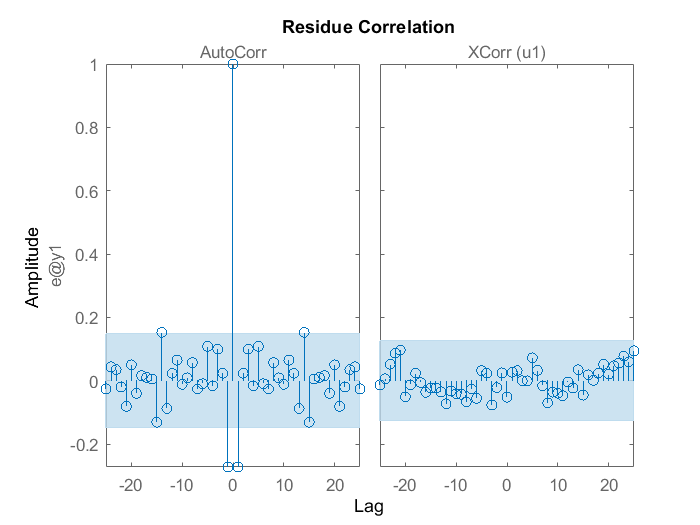

resid(z,th);

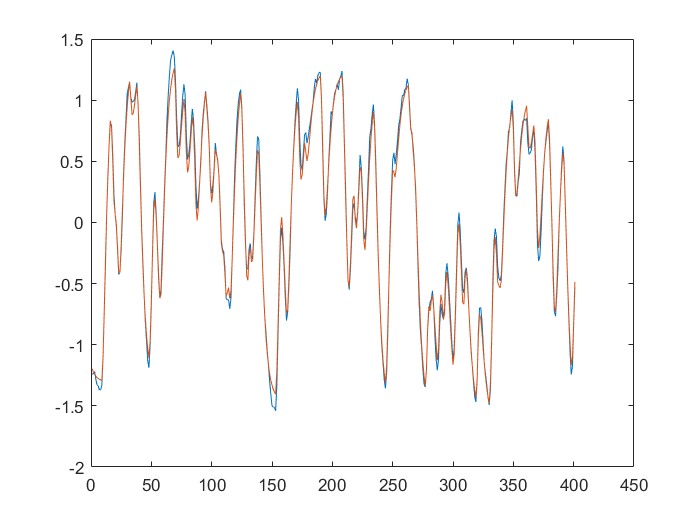

u = detrend(u(501:1000));
y = detrend(y(501:1000));
ysim = sim(u,th);
plot([y(100:500) ysim(100:500)])

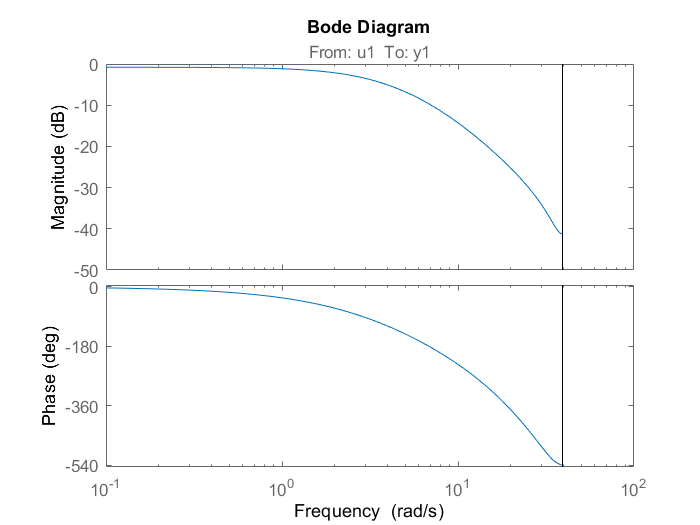

%Freq Response
gth = th2ff(th);
bodeplot(gth)

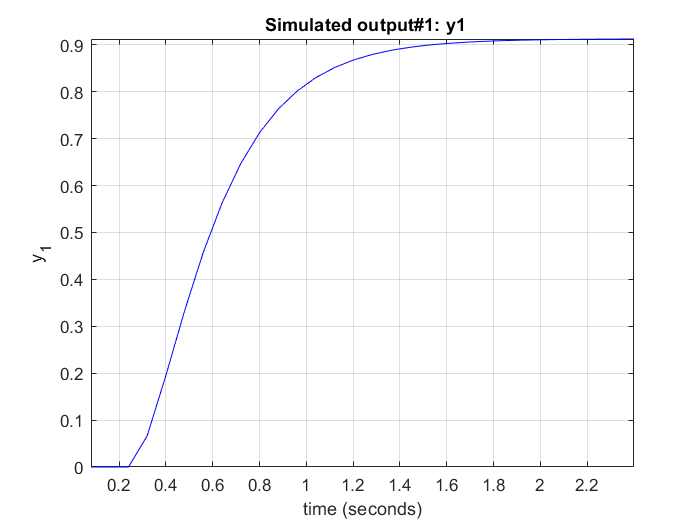

%Step Response 
step = ones(30,1);
idsimsd(step,th)